# My Falcon 9 multistage sim

## Introduction & Equations of Motion

The purpose of this project is to model the 2 stage flight of the falcon 9, based on different assumptions. 

The rockets equations are based on Newtons 2nd law. The position and velocity vectors are split into vectors with x and y values. So, we have the state vector [x,y,Vx,Vy]. These are the forces we use as well: 

Thrust is T0 * [sintheta costheta] as it is constant. Aerodynamic drag is -1/2*rho*V_mag*(pi*dia_F9^2/4)*Cd*[Vx;Vy]. Where rho (the density) has to be calculated as rho = rho0*exp(-0.00012*h) if it . A is the cross sectional area (given by pi*r^2) and V is velocity. During all stages, the mass decreases linearly with time, giving m(t) = m0-mdot * t. 

In general, the system of ODE has the big equation that dVx/dt = Tx+Dx+Fgx/m, and same for the y. We input all these equations, and then based on the assumptions made, we narrow the values down in each case.

In general, here is all our data starting out. 

## Data

% data
g0 = 9.81; % m/s^2
dia_F9 = 3.7; % m
Cd = 0.6;
rho0 = 1.225; % kg/m^3
RE = 6378e3; %m

## Case 1:

#### Stage 1:

% Initial Conditiona
x0 = 0;
y0 = RE;
Vx0 = 0;
Vy0 = 0;

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t1,q] = ode45(@Falcon9C1S1,[0 160],q0);

Falcon9C1S1 is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\dhany\Downloads\Dynamics

Change the MATLAB current folder or add its folder to the MATLAB path.

Error in odearguments (line 92)
f0 = ode(t0,y0,args{:});   % ODE15I sets args{1} to yp0.

Error in 


x1 = q(:,1);
y1 = q(:,2);
Vx1 = q(:,3);
Vy1 = q(:,4);

plot(x1,y1,'r')
title('Case 1')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
axis equal

plot(t1,sqrt(Vx1.^2+Vy1.^2))
title('Case 1')
xlabel('time (s)')
ylabel('speed (m/s)')

#### Stage 2

% Initial Conditiona
x0 = x1(end);
y0 = y1(end);
Vx0 = Vx1(end);
Vy0 = Vy1(end);

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t2,q] = ode45(@Falcon9C1S2,[160 560],q0);

x2 = q(:,1);
y2 = q(:,2);
Vx2 = q(:,3);
Vy2 = q(:,4);

plot(x1,y1,'r',x2,y2,'b','LineWidth',2)
title('Case 1')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
axis equal
%hold on
%rectangle('Position',[-RE -RE 2*RE 2*RE],'Curvature',[1 1],'FaceColor',[.5 1 1],'EdgeColor','k') 

%hold off

plot(t1,sqrt(Vx1.^2+Vy1.^2),'r',t2,sqrt(Vx2.^2+Vy2.^2),'b')
title('Case 1')
xlabel('time (s)')
ylabel('speed (m/s)')

## Case 1 Discussion

In case 1, the simplifying assumption are: constant thrust and gravity, no drag, and a flat earth. Stage one is perfectly vertical (Theta = 0) while stage 2 tilts to theta = 45 degrees. With no drag, we set the drag equations to 0. As velocity grows steadily, the largest acceleration will be during stage 1, as a result of it having the highest weight to thrust ratio. Overall, I think this case was really good in making us more profient with using the ODE solver in MATLAB. I also think, it helped us understand the pressure value, as it is now changing, and how to integrate that into our simulations. 

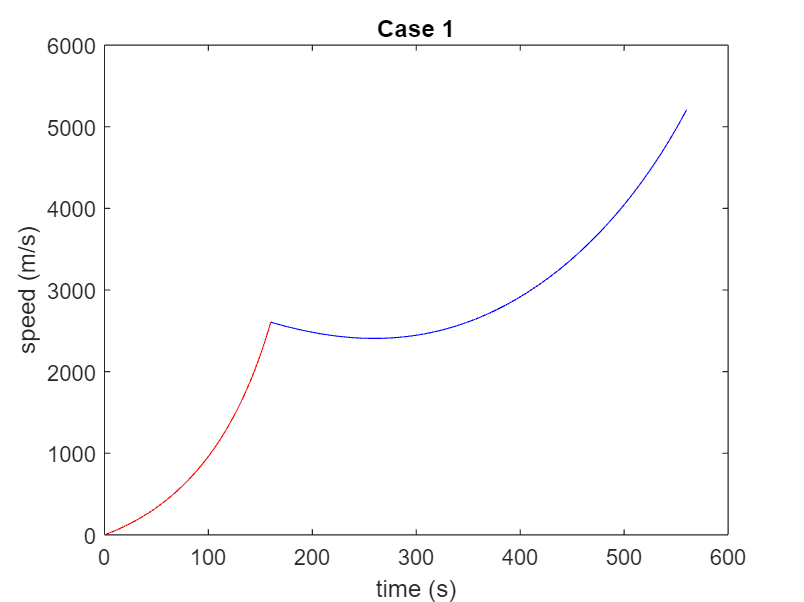

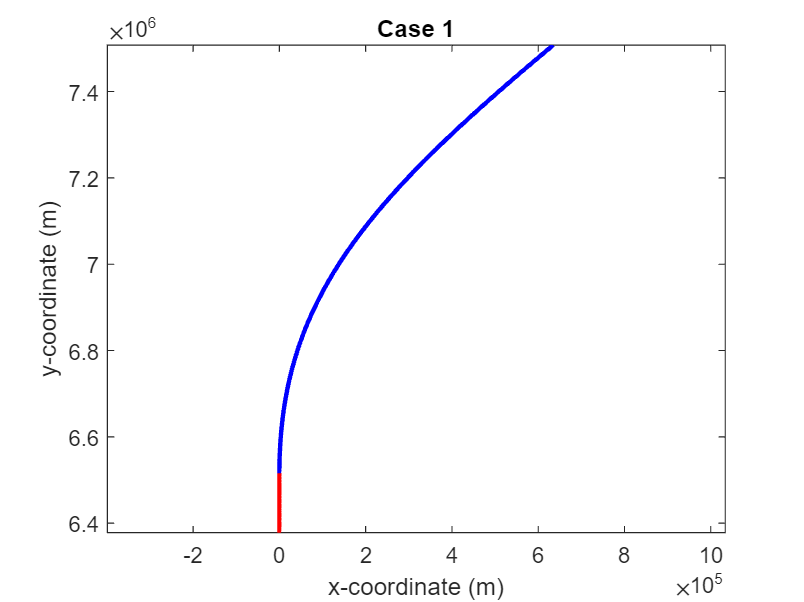

## Case 2:

#### Stage 1

% Initial Conditiona
x0 = 0;
y0 = RE;
Vx0 = 0;
Vy0 = 0;

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t1,q] = ode45(@Falcon9C2S1,[0 160],q0);

x1 = q(:,1);
y1 = q(:,2);
Vx1 = q(:,3);
Vy1 = q(:,4);

plot(x1,y1,'r')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
title('Case 2')
axis equal

plot(t1,sqrt(Vx1.^2+Vy1.^2))
title('Case 2')
xlabel('time (s)')
ylabel('speed (m/s)')

#### Stage 2

% Initial Conditiona
x0 = x1(end);
y0 = y1(end);
Vx0 = Vx1(end);
Vy0 = Vy1(end);

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t2,q] = ode45(@Falcon9C2S2,[160 560],q0);

x2 = q(:,1);
y2 = q(:,2);
Vx2 = q(:,3);
Vy2 = q(:,4);

plot(x1,y1,'r',x2,y2,'b','LineWidth',2)
title('Case 2')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
axis equal
hold on
rectangle('Position',[-RE -RE 2*RE 2*RE],'Curvature',[1 1],'FaceColor',[.5 1 1],'EdgeColor','k') 

hold off

plot(t1,sqrt(Vx1.^2+Vy1.^2),'r',t2,sqrt(Vx2.^2+Vy2.^2),'b')
title('Case 2')
xlabel('time (s)')
ylabel('speed (m/s)')

#### Payload Orbit

% Initial Conditiona
x0 = x2(end);
y0 = y2(end);
Vx0 = Vx2(end);
Vy0 = Vy2(end);

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t3,q] = ode45(@Falcon9Payload,[560 3136],q0);

x3 = q(:,1);
y3 = q(:,2);
Vx3 = q(:,3);
Vy3 = q(:,4);

plot(x1,y1,'r',x2,y2,'b',x3,y3,'y','LineWidth',2)
title('Case 2')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
axis equal
hold on
rectangle('Position',[-RE -RE 2*RE 2*RE],'Curvature',[1 1],'FaceColor',[.5 1 1],'EdgeColor','k') 

hold off

plot(t1,sqrt(Vx1.^2+Vy1.^2),'r',t2,sqrt(Vx2.^2+Vy2.^2),'b',t3,sqrt(Vx3.^2+Vy3.^2),'y')
title('Case 2')
xlabel('time (s)')
ylabel('speed (m/s)')

## **Case** 2 Discussion/ Reflection

In case 2, the most noticable difference is the inclusion of drag and also the changing gravity. As a result of the drag, the rockets accelaration dramatically decreases in stage 1 compared to case 1. However, the variable gravity reduces the gravitational pull as we get farther away from earth, which helps accelaration in the later stages. The rocket's altitude and velocity are a lot different than case 1, but I would say more accurate as the gravity and drag are important pieces of the forces in play. 

For the playload orbit, we can see that it starts to go on a orbit, but soon crashes into earth. This shows how we need more thrust/ velocity, so we can escape the gravitational pull of earth more so we can go in a elliptical orbit instead of crashing. 

The most important thing the group learned during the creation of this simulation was how to include a circular earth, and also how to simulate the orbit of a payload. Overall, this was a good simulation which taught us a lot about simulating orbits, and how to see if our orbit is successful or not. 

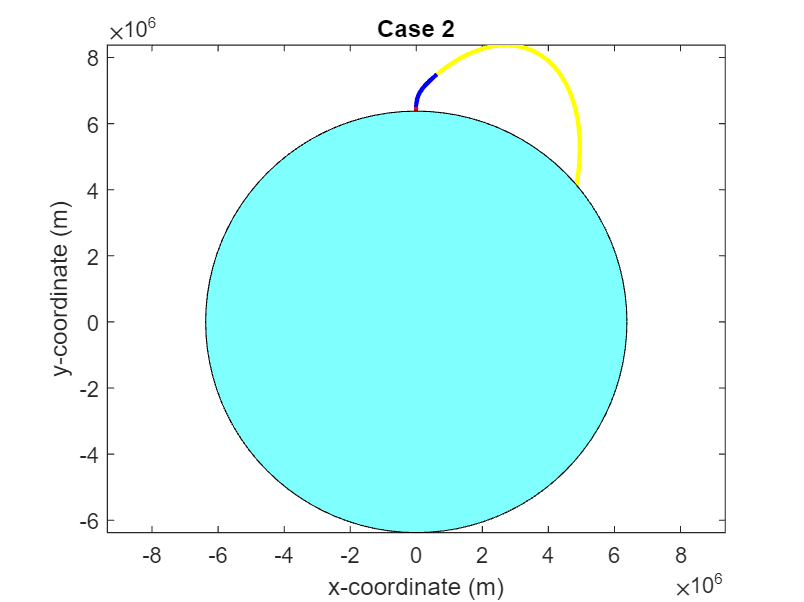

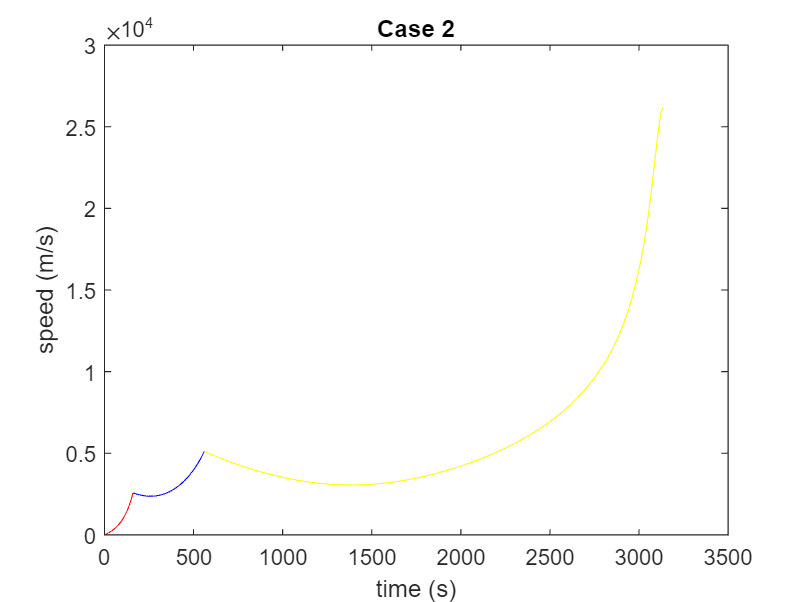

## Case 3:

## Stage 1

% Initial Conditiona
x0 = 0;
y0 = RE;
Vx0 = 0;
Vy0 = 0;

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t1,q] = ode45(@Falcon9C3S1,[0 160],q0);

x1 = q(:,1);
y1 = q(:,2);
Vx1 = q(:,3);
Vy1 = q(:,4);

plot(x1,y1,'r')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
title('Case 3')
axis equal

plot(t1,sqrt(Vx1.^2+Vy1.^2))
title('Case 3')
xlabel('time (s)')
ylabel('speed (m/s)')


## Stage 2

% Initial Conditiona
x0 = x1(end);
y0 = y1(end);
Vx0 = Vx1(end);
Vy0 = Vy1(end);

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t2,q] = ode45(@Falcon9C3S2,[160 560],q0);

x2 = q(:,1);
y2 = q(:,2);
Vx2 = q(:,3);
Vy2 = q(:,4);

plot(x1,y1,'r',x2,y2,'b','LineWidth',2)
title('Case 3')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
axis equal
hold on
rectangle('Position',[-RE -RE 2*RE 2*RE],'Curvature',[1 1],'FaceColor',[.5 1 1],'EdgeColor','k') 

hold off

plot(t1,sqrt(Vx1.^2+Vy1.^2),'r',t2,sqrt(Vx2.^2+Vy2.^2),'b')
title('Case 3')
xlabel('time (s)')
ylabel('speed (m/s)')


## **Payload Orbit**

% Initial Conditiona
x0 = x2(end);
y0 = y2(end);
Vx0 = Vx2(end);
Vy0 = Vy2(end);

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t3,q] = ode45(@Falcon9Payload,[560 4000],q0);

x3 = q(:,1);
y3 = q(:,2);
Vx3 = q(:,3);
Vy3 = q(:,4);

plot(x1,y1,'r',x2,y2,'b',x3,y3,'y','LineWidth',2)
title('Case 3')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
axis equal
hold on
rectangle('Position',[-RE -RE 2*RE 2*RE],'Curvature',[1 1],'FaceColor',[.5 1 1],'EdgeColor','k') 

hold off

plot(t1,sqrt(Vx1.^2+Vy1.^2),'r',t2,sqrt(Vx2.^2+Vy2.^2),'b',t3,sqrt(Vx3.^2+Vy3.^2),'y')
title('Case 3')
xlabel('time (s)')
ylabel('speed (m/s)')

Earth impact around 4000s

## **Case** 3: Discussion and Reflection

In Case 3, the only difference that it has from case 2 is the angle over time. Now during stage 1 the angle increases linearly from 0 to 45 degrees linearly with time. During stage 2 the angle goes from 45 to 90 degrees linearly. With these changes our top speed is lower than what is was in case 2. As well as our altitude in the y direction, but the altitude did increase in the x direction. Compared to case 2 our orbit around the earth is better. Even though we do crash into the earth we go farther than we did in case 2. The path of our orbit is better in case 3, which shows our orientation over time is improving.

Case 3 demonstrated how many improvements can be made to our orbit without any changes to the thrust of the rocket. Which really highlighted the importance of the angles(orientation) of the rocket and how it affects your velocity and altitude. Case 3 gave us a better understanding of the relationships within the rocket and how one change can cause major effects.

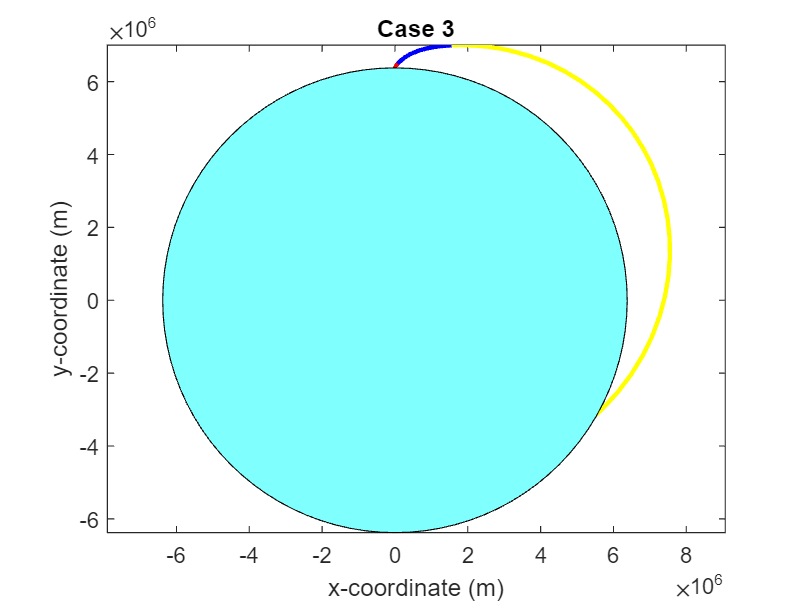

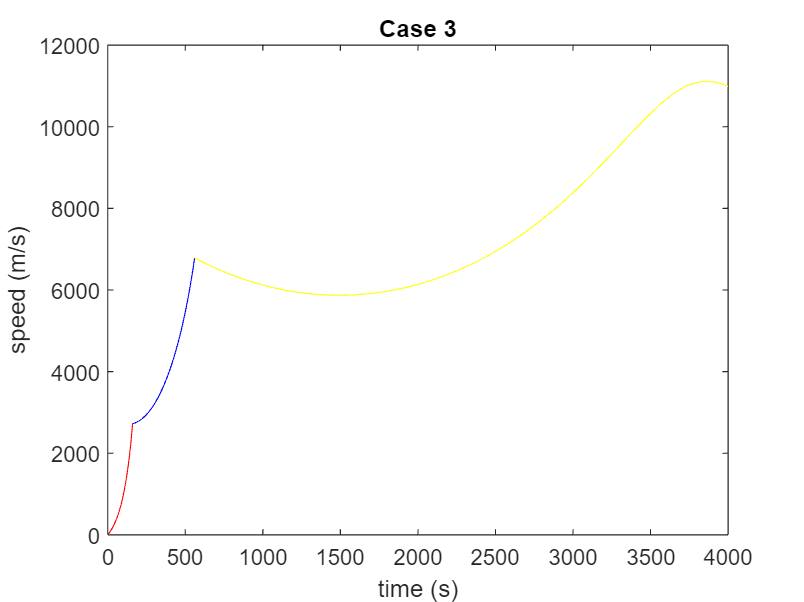

## Case 4:

## Stage 1

% Initial Conditiona
x0 = 0;
y0 = RE;
Vx0 = 0;
Vy0 = 0;

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t1,q] = ode45(@Falcon9C4S1,[0 160],q0);

x1 = q(:,1);
y1 = q(:,2);
Vx1 = q(:,3);
Vy1 = q(:,4);

plot(x1,y1,'r')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
title('Case 4')
axis equal

plot(t1,sqrt(Vx1.^2+Vy1.^2))
title('Case 4')
xlabel('time (s)')
ylabel('speed (m/s)')


## Stage 2

% Initial Conditiona
x0 = x1(end);
y0 = y1(end);
Vx0 = Vx1(end);
Vy0 = Vy1(end);

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t2,q] = ode45(@Falcon9C4S2,[160 560],q0);

x2 = q(:,1);
y2 = q(:,2);
Vx2 = q(:,3);
Vy2 = q(:,4);

plot(x1,y1,'r',x2,y2,'b','LineWidth',2)
title('Case 4')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
axis equal
hold on
rectangle('Position',[-RE -RE 2*RE 2*RE],'Curvature',[1 1],'FaceColor',[.5 1 1],'EdgeColor','k') 

hold off

plot(t1,sqrt(Vx1.^2+Vy1.^2),'r',t2,sqrt(Vx2.^2+Vy2.^2),'b')
title('Case 4')
xlabel('time (s)')
ylabel('speed (m/s)')


## **Payload Orbit**

% Initial Conditiona
x0 = x2(end);
y0 = y2(end);
Vx0 = Vx2(end);
Vy0 = Vy2(end);

q0 = [x0;y0;Vx0;Vy0];

% Simulation
[t3,q] = ode45(@Falcon9Payload,[560 10000],q0);

x3 = q(:,1);
y3 = q(:,2);
Vx3 = q(:,3);
Vy3 = q(:,4);

plot(x1,y1,'r',x2,y2,'b',x3,y3,'y','LineWidth',2)
title('Case 4')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
axis equal
hold on
rectangle('Position',[-RE -RE 2*RE 2*RE],'Curvature',[1 1],'FaceColor',[.5 1 1],'EdgeColor','k') 

hold off

plot(t1,sqrt(Vx1.^2+Vy1.^2),'r',t2,sqrt(Vx2.^2+Vy2.^2),'b',t3,sqrt(Vx3.^2+Vy3.^2),'y')
title('Case 4')
xlabel('time (s)')
ylabel('speed (m/s)')

## Case 4: Disscussion and Refelction

In Case 4, the design of the launch was up to us. Our goal was to find to see how far along our orbit we could go before crashing into the earth. How the orientation of the rocket changed over time was the variable we were able to change. Throught trial and error we were able to find the optimal orientation over time for our rocket. For stage 1 the angle goes from 0 to 55 degrees which differs from case 3 where the highest angle for stage 1 was 45 degrees. For stage 2 the highest angle of orientation is 115 degrees. This allowed the rocket to orbit the earth without crashing into it, like what happend in case 2 and 3. Similarly to the outcomes in case 3, our top speed has decreesed from our last case. Our altitude in both the x and y direction have also decressed as well.

Case 4 allowed us to edit the orientation or our rocket. Through this process we built on what we took away from case 3. WIth us bieng able to go through multiple trials we were able to get a fuller picture of the different effects the orientation of the rocket causes. We were able to decrease/increase the angle and change the orientation over time and see how it affected the orbit. Which allowed us to solidify our understanding of how all the different variables are intertwined.